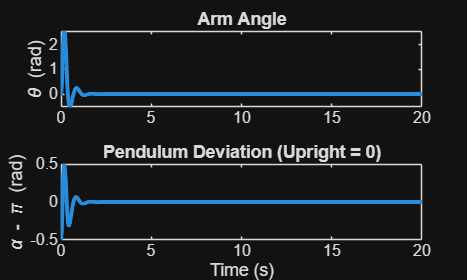

%% QUBE-Servo 3 Rotary Inverted Pendulum Simulation
% Nonlinear model + PD control for upright stabilization

clear; clc; close all;

%% =========================
% 1. PARAMETERS (FROM TABLE)
% =========================

% Motor parameters
Rm = 7.5;              % Ohm
kt = 0.0422;           % N·m/A
km = 0.0422;           % V/(rad/s)
Jm = 1.4e-6;           % kg·m^2

% Hub
Jh = 0.6e-6;           % kg·m^2

% Rotary arm
mr = 0.095;            % kg
Lr = 0.085;            % m

% Pendulum
mp = 0.024;            % kg
Lp = 0.129;            % m
lp = Lp/2;             % COM distance (assume uniform rod)

% Gravity
g = 9.81;              % m/s^2

% Total rotary inertia
Jr = Jm + Jh;

% Pendulum inertia about pivot (rod about one end)
Jp = (1/3)*mp*Lp^2;

%% =========================
% 2. PD CONTROLLER GAINS
% =========================
%tune them god dammit

k1 = 60;   % pendulum angle gain
k2 = 9;    % pendulum damping
k3 = 9;    % arm position penalty
k4 = 3;    % arm damping

%% =========================
% 3. SIMULATION SETTINGS
% =========================

tspan = [0 20];   % simulation time

% Initial condition:
% [theta, alpha, theta_dot, alpha_dot]
x0 = [0; pi-0.5; 0; 0];  
% small deviation from upright

%% =========================
% 4. RUN SIMULATION
% =========================
% maybe fix of runaway computing problem
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9, 'MaxStep', 0.01);
[t, x] = ode15s(@(t,x) dynamics(t,x), tspan, x0, options);
%[t, x] = ode45(@(t,x) dynamics(t,x), tspan, x0);

theta = x(:,1);
alpha = x(:,2);

%% =========================
% 5. PLOTS
% =========================

figure;
subplot(2,1,1)
plot(t, theta, 'LineWidth', 2)
ylabel('\theta (rad)')
title('Arm Angle')

subplot(2,1,2)
plot(t, alpha - pi, 'LineWidth', 2)
ylabel('\alpha - \pi (rad)')
xlabel('Time (s)')
title('Pendulum Deviation (Upright = 0)')


%% =========================
% 6. DYNAMICS FUNCTION
% =========================

function dx = dynamics(~, x)

    % Access variables from base workspace
    Rm = evalin('base','Rm');
    kt = evalin('base','kt');
    km = evalin('base','km');
    Jr = evalin('base','Jr');
    Jp = evalin('base','Jp');
    mp = evalin('base','mp');
    Lr = evalin('base','Lr');
    lp = evalin('base','lp');
    g  = evalin('base','g');

    k1 = evalin('base','k1');
    k2 = evalin('base','k2');
    k3 = evalin('base','k3');
    k4 = evalin('base','k4');

    % States
    
    theta = x(1);
    alpha = x(2);
    theta_dot = x(3);
    alpha_dot = x(4);

    % =========================
    % CONTROL LAW (PD)
    % =========================
    
    % Deviation from upright
    alpha_tilde =  alpha - pi;

    % PD controller
    V_unsat = -(k1*alpha_tilde ...
      + k2*alpha_dot ...
      - k3*theta ...
      - k4*theta_dot);
    V_max = 10;
    V = max(min(V_unsat,V_max),-V_max);

    % Motor torque
    tau = (kt/Rm)*(V - km*theta_dot);

    % =========================
    % SYSTEM DYNAMICS
    % =========================

    % Mass matrix
    M = [Jr + mp*Lr^2 + mp*lp^2*sin(alpha)^2,   mp*Lr*lp*cos(alpha);
         mp*Lr*lp*cos(alpha),                 Jp + mp*lp^2];

    % Coriolis / centrifugal
    C = [2*mp*lp^2*sin(alpha)*cos(alpha)*theta_dot*alpha_dot ...
         - mp*Lr*lp*sin(alpha)*alpha_dot^2;
         
         -mp*lp^2*sin(alpha)*cos(alpha)*theta_dot^2];

    % Gravity
    G = [0;
         mp*g*lp*sin(alpha)];

    % Solve accelerations
    qdd = M \ ([tau; 0] - C - G);

    % =========================
    % STATE DERIVATIVE
    % =========================

    dx = zeros(4,1);
    dx(1) = theta_dot;
    dx(2) = alpha_dot;
    dx(3) = qdd(1);
    dx(4) = qdd(2);

end

